# Optimización para hallar coeficientes de la ecuación de van Deemter

Resultados de un experimento HPLC dónde se registraron altura de plato (H) y velocidad de la fase movil (u)


$$H=A+\frac{B}{u}+Cu$$


A: Eddy diffusion

B: Longitudinal difussion

C: Mass transfer

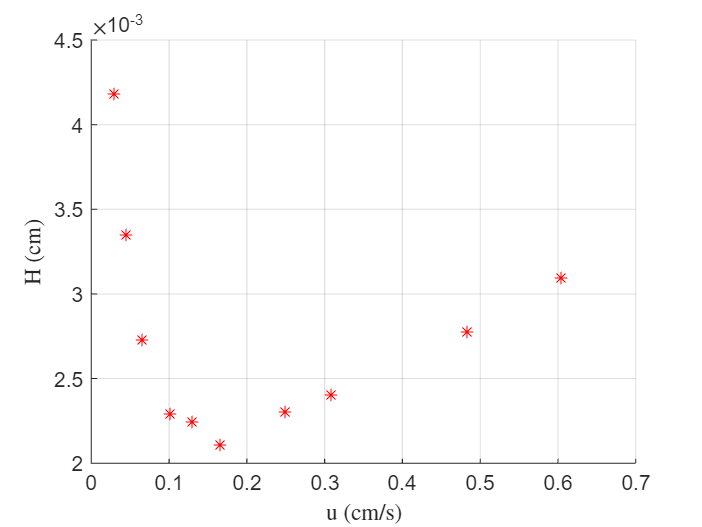

clc, clear all;
format long
% Datos experimentales
u=[0.03037 0.04521 0.06527 0.1017 0.1295 0.1659 0.2496 0.3082 0.4839 0.6042];
H=[0.004182 0.003352 0.002731 0.002293 0.002246 0.00211 0.002305 0.002407 0.002778 0.003098];

% Previsualización de datos
scatter(u,H,'r*')
xlabel('u (cm/s)','Interpreter','latex')
ylabel('H (cm)','Interpreter','latex')
grid on

% Definir la ecuación de van Deemter
modelo=@(params,u)params(1)+params(2)./u+params(3)*u;

% Establecer valores iniciales para A, B y C
params0=[1e-3 1e-6 1e-3];

% Realizar el ajuste de curva
params_opt=lsqcurvefit(modelo,params0,u,H);


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


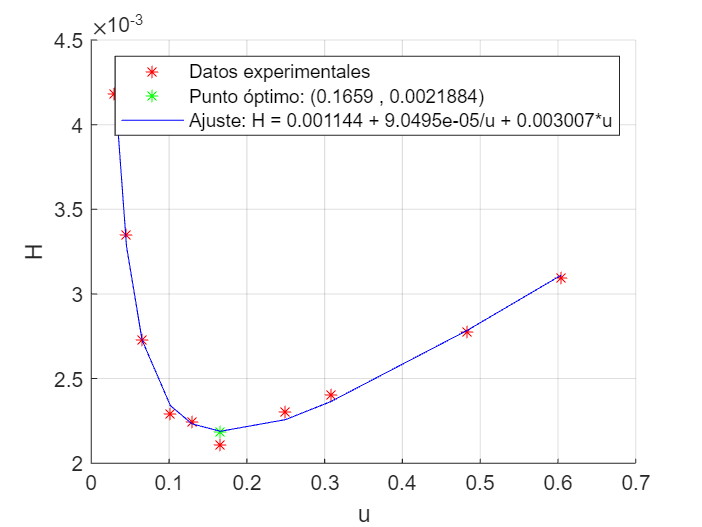


% Obtener los valores ajustados de A, B y C
A_opt=params_opt(1);
B_opt=params_opt(2);
C_opt=params_opt(3);

% Calcular los valores predichos
H_pred=modelo(params_opt,u);

% Graficar los datos y la curva ajustada
figure;
scatter(u,H,'r*','DisplayName','Datos experimentales');
hold on;
scatter(u(6),modelo(params_opt, u(6)),'g*','DisplayName',['Punto óptimo: (',num2str(u(6)),' , ',num2str(modelo(params_opt, u(6))),')']);
plot(u,H_pred,'b','DisplayName',['Ajuste: H = ',num2str(A_opt),' + ',num2str(B_opt),'/u + ',num2str(C_opt),'*u']);
xlabel('u');
ylabel('H');
legend('show');
grid on;
hold off